A=xlsread("附件.xlsx");%xy坐标数据

ST=[9 10.5 12 13.5 15]; % 当地时间
D=[310,341,0,31,61,92,122,153,184,224,255,285]; % 春分起天数
phi=39.4*pi/180; % 纬度
omega=pi*(ST-12)/12; % 太阳时角

% 预分配内存
alphas = zeros(length(D), length(ST));
gamas = zeros(length(D), length(ST));

det = asin(sin(2*pi*D/365)*sin(2*pi/360*23.45)); % 赤纬角

for i = 1:length(det)
    deta = det(i);
    alphas(i,:) = asin(cos(deta).*cos(phi).*cos(omega) + sin(deta).*sin(phi)); % 高度角
    gamas(i,:) = real(acos((sin(deta) - sin(alphas(i,:)).*sin(phi)) ./ (cos(alphas(i,:)).*cos(phi)))); % 方位角
end
%入射光线单位向量
ga=cos(alphas).*sin(gamas);
gb=cos(alphas).*cos(gamas);
gc=sin(alphas);

DNI=1.366*(0.4237-0.00821*9+(0.5055+0.00595*3.5*3.5).*exp(-(0.2711+0.01858*0.25)./sin(alphas)));%DNI
%z方向为-80
z = -80 * ones(size(A, 1), 1);
Rz=[A,z];
%镜面坐标系下z轴方向向量
zj=-(Rz + repmat(i, size(A, 1), 1)) / 2 ;
%两个z轴间夹角EH
EH = atan((zj(:,1).^2+zj(:,2).^2)./zj(:,3)) ;
%变换后z轴的投影与正半轴夹角
AH = atan(zj(:,2)./zj(:,1)) ;
l=88./tan(alphas);

%初始化参数
n_points = 1000; % 在每个镜面上随机选取点进行模拟
n_mirrors = 1745;
%坐标
mirror_coords = A;
% 初始化阴影遮挡效率数组
eta_sb = zeros(n_mirrors, 60);
%太阳光向量I遍历
for m=1:12
    for n=1:5
        I=[ga(m,n),gb(m,n),gc(m,n)];

        % 对每一对镜面组合进行迭代
        for j = 1:n_mirrors
            k=0;
            for i=1:n_mirrors
                if i == j
                    continue;
                end

                % 获取镜面i和镜面j的坐标
                x_i = mirror_coords(i, 1);
                y_i = mirror_coords(i, 2);
                x_j = mirror_coords(j, 1);
                y_j = mirror_coords(j, 2);
                sah=sin(AH(i));
                cah=cos(AH(i));
                seh=sin(EH(i));
                ceh=cos(EH(i));
                sahj=sin(AH(j));
                cahj=cos(AH(j));
                sehj=sin(EH(j));
                cehj=cos(EH(j));
                % 计算转换矩阵
                T_i = [-sah,-cah*ceh,cah*seh;cah,-sah*ceh,sah*seh;0,seh,ceh];
                T_j = [-sahj,-cahj*cehj,cahj*sehj;cahj,-sahj*cehj,sahj*sehj;0,sehj,cehj];

                % 镜面i和镜面j中心在H0下的坐标
                O_i = [x_i, y_i, 4];
                O_j = [x_j, y_j, 4];

                % 对每一个镜面i上的点进行迭代

                % 在镜面i上随机选择一个点（这里镜面大小为6x6）

                H1_Hi = [(rand(n_points,2)*2-1)*3,zeros(n_points,1)];

                % 将 H1 从 Hi 转换到 H0
                H1_H0 = T_i * H1_Hi' + O_i';

                % 再将 H1 从 H0 转换到 Hj
                H1_Hj = T_j \ (H1_H0 - O_j');

                % 光线向量在 H0 下迭代
                V_H0 = I;

                % 将光线向量从 H0 转换到 Hj
                V_Hj = T_j\ V_H0';

                % 计算落在镜面j上的坐标 H2
                a = V_Hj(1); b = V_Hj(2); c = V_Hj(3);
                x1 = H1_Hj(1,:); y1 = H1_Hj(2,:); z1 = H1_Hj(3,:);
                t = -z1 / c;
                x2 = x1 + a * t;
                y2 = y1 + b * t;

                % 判断 H2 是否落在镜面j内（这里镜面大小为6x6）
                k=k+length(find(abs(x2) <= 3 & abs(y2) <= 3));
            end
            ii=5*(m-1)+n;%计数器
            eta_sb(j,ii)=1-k/n_points;
        end
    end
end


% 输出结果
disp(eta_sb);


% 初始化参数
n_points = 30000; % 在每个镜面上随机选取30000个点进行模拟
n_mirrors = 1745;
% % %坐标
mirror_coords = A;
tao=(rand(n_points,1)*2-1)*0.00465+pi/2;%tao的值在[pi/2-4.65e-3,pi/2+4.65e-3]之间
sigma=rand(n_points,1)*0.00465;%sigma值在[0,4.65e-3]之间
XY=[(rand(n_points,2)*2-1)*3,zeros(n_points,1)]%H_1的xy坐标
Ss=[sin(sigma).*cos(tao),sin(sigma).*sin(tao),cos(tao)];%向量Ss
eta_t=zeros(n_mirrors,1);
zz=zeros(n_points, n_mirrors);
for i=1:n_mirrors
    x_i = mirror_coords(i, 1);
    y_i = mirror_coords(i, 2);
    X_i = [1 0 0];%x轴向量
    Z_i = [cos(AH(i))*sin(EH(i)) sin(AH(i))*sin(EH(i)) cos(EH(i))];%z轴向量
    Y_i = cross(X_i,Z_i);
    Tt_i=[X_i' Z_i' Y_i'];
    Tt_i=Tt_i/norm(Tt_i); % 转换矩阵
    sah=sin(AH(i));
    cah=cos(AH(i));
    seh=sin(EH(i));
    ceh=cos(EH(i));
    % 计算转换矩阵
    T_i = [-sah,-cah*ceh,cah*seh;cah,-sah*ceh,sah*seh;0,seh,ceh];
    O_i = [x_i, y_i, 4];
    XY_H0 = T_i * XY' + O_i';%H1|HA--H1|H0
    Ss_H0 = Tt_i * Ss';%Ss|HS--Ss|H0
    OAZA = T_i * [0 0 1]';%OAZA|HA--OAZA|H0
    m=Ss_H0(1,:); n = Ss_H0(2,:); l = Ss_H0(3,:);
    x1 = XY_H0(1,:); y1 = XY_H0(2,:); z1 = XY_H0(3,:);
    % 定义目标函数
    FF = @(zz) ((m'.*(zz-z1')./l'+x1').^2+((n'.*(zz)-z1')./l'+y1').^2-49/4).^2;

    % 初始猜测值
    x0 = zeros(n_points, 1) + 88;  % 设置初始值

    % 设置优化选项
    options = optimoptions('lsqnonlin', 'Display', 'off');
    options.Algorithm = 'levenberg-marquardt';
    % 进行非线性最小二乘优化
    [zz(:,i),aa,aaa,saaaa] = lsqnonlin(FF, x0, [], [], options)
    eta_t(:,i)=(length(find(76<=zz(:,i)&zz(:,i)<=4)))/n_points;
end

% 初始化参数
n_points = 30000; % 在每个镜面上随机选取30000个点进行模拟
n_mirrors = 1745;
% % %坐标
mirror_coords = A;
% % 初始化阴影遮挡效率数组
etasb1 = zeros(n_mirrors, 60);
%太阳光向量I遍历
for m=1:12
    for n=1:5
        I=[ga(m,n),gb(m,n),gc(m,n)];

        % 对每一对镜面组合进行迭代
        for j = 1:n_mirrors
            k=0;

            % 获取吸收塔ddd和镜面j的坐标
            x_j = mirror_coords(j, 1);
            y_j = mirror_coords(j, 2);
            sahj=sin(AH(j));
            cahj=cos(AH(j));
            sehj=sin(EH(j));
            cehj=cos(EH(j));
            % 计算转换矩阵
            T_j = [-sahj,-cahj*cehj,cahj*sehj;cahj,-sahj*cehj,sahj*sehj;0,sehj,cehj];

            %镜面j中心在H0下的坐标
            O_j = [zeros(n_points,1)+x_j, zeros(n_points,1)+y_j, zeros(n_points,1)+4];

            % 对每一个吸收塔ddd上的点进行迭代

            % 在吸收塔ddd上随机选点
            H1_H0 = [(rand(n_points,2)*2-1)*3.5 rand(n_points,1)*84];

            % 再将 H1 从 H0 转换到 Hj
            H1_Hj = T_j \( H1_H0' - O_j');

            % 光线向量在 H0 下迭代
            V_H0 = I;

            % 将光线向量从 H0 转换到 Hj
            V_Hj = T_j\ V_H0';

            % 计算落在镜面j上的坐标 H2
            a = V_Hj(1); b = V_Hj(2); c = V_Hj(3);
            x1 = H1_Hj(1,:); y1 = H1_Hj(2,:); z1 = H1_Hj(3,:);
            t = -z1 / c;
            x2 = x1 + a * t;
            y2 = y1 + b * t;

            % 判断 H2 是否落在镜面j内（这里镜面大小为6x6）
            k=k+length(find(abs(x2) <= 3 & abs(y2) <= 3));
            ii=5*(m-1)+n;%计数器
            etasb1(j,ii)=1-k/n_points;
        end
    end
end



% 输出结果
disp(etasb1);

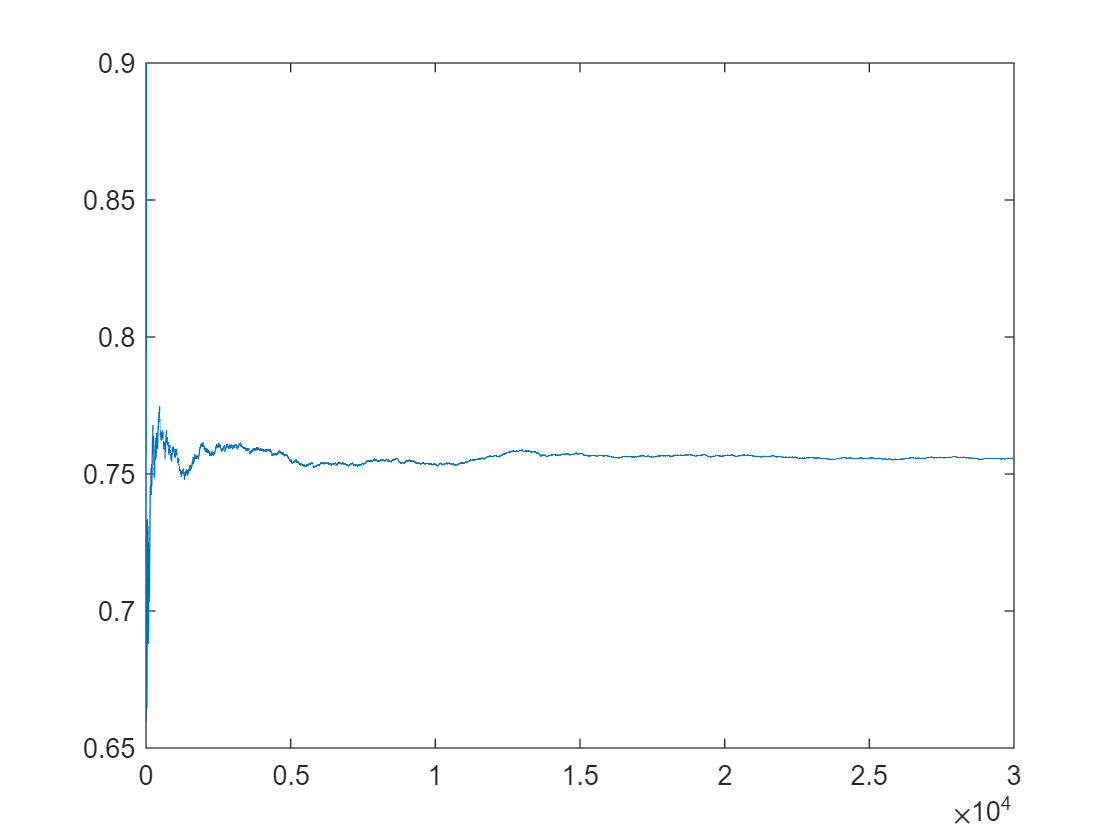

%模型检验
n_points = 30000; % 在每个镜面上选取30000个点进行模拟
n_mirrors = 1745;
%坐标
mirror_coords = A;
% 初始化阴影遮挡效率数组
eta_sb = zeros(n_mirrors, 60);
%太阳光向量I遍历

I=[ga(1,1),gb(1,1),gc(1,1)];

% 对每一对镜面组合进行迭代
i=145;

j=80;
% 获取镜面i和镜面j的坐标
x_i = mirror_coords(i, 1);
y_i = mirror_coords(i, 2);
x_j = mirror_coords(j, 1);
y_j = mirror_coords(j, 2);
sah=sin(AH(i));
cah=cos(AH(i));
seh=sin(EH(i));
ceh=cos(EH(i));
sahj=sin(AH(j));
cahj=cos(AH(j));
sehj=sin(EH(j));
cehj=cos(EH(j));
% 计算转换矩阵
T_i = [-sah,-cah*ceh,cah*seh;cah,-sah*ceh,sah*seh;0,seh,ceh];
T_j = [-sahj,-cahj*cehj,cahj*sehj;cahj,-sahj*cehj,sahj*sehj;0,sehj,cehj];

% 镜面i和镜面j中心在H0下的坐标
O_i = [x_i, y_i, 4];
O_j = [x_j, y_j, 4];

% 对每一个镜面i上的点进行迭代

% 在镜面i上随机选择一个点（这里镜面大小为6x6）

H1_Hi = [(rand(n_points,2)*2-1)*3,zeros(n_points,1)];

% 将 H1 从 Hi 转换到 H0
H1_H0 = T_i * H1_Hi' + O_i';

% 再将 H1 从 H0 转换到 Hj
H1_Hj = T_j \ (H1_H0 - O_j');

% 光线向量在 H0 下循环
V_H0 = I;

% 将光线向量从 H0 转换到 Hj
V_Hj = T_j\ V_H0';

% 计算落在镜面j上的坐标 H2
a = V_Hj(1); b = V_Hj(2); c = V_Hj(3);
x1 = H1_Hj(1,:); y1 = H1_Hj(2,:); z1 = H1_Hj(3,:);
t = -z1 / c;
x2 = x1 + a * t;
y2 = y1 + b * t;


% 判断 H2 是否落在镜面j内（这里镜面大小为6x6）
for aaaa=1:30000
    kkkkkk(aaaa,1)=0.9-length(find(abs(x2(1:aaaa)) <= 3 & abs(y2(1:aaaa)) <= 3))/aaaa;

end

% 输出结果
plot(kkkkkk)

tiledlayout('flow')
for i=1:4
% XY数据
X = A(:,1); % X
Y = A(:,2); % Y
Z = eta(:,15*i-14); % eta值
 nexttile
% 创建散点图
scatter(X,Y,15,Z,'filled') % 15是点的大小，'filled'表示填充点

% 添加颜色条
colorbar

% 添加标题
xlabel('x坐标')
ylabel('y坐标')
titleStr = sprintf('第%d季度光学效率', i);  % 使用sprintf来格式化字符串
title(titleStr);
% 设置颜色轴的范围以匹配数据
caxis([0 1])
end